%% ============================================================
% MODULE 1 : UAV Parameters & Initialization
% ============================================================
clear;
clc;
close all;
%% Physical Parameters
params.m = 1.5;                 % Mass (kg)
params.g = 9.81;                % Gravity (m/s^2)
%% Inertia Matrix
params.J = [0.0348 0      0;
            0      0.0459 0;
            0      0      0.0977];

params.Jinv = inv(params.J);
%% Simulation Parameters
params.dt = 0.001;              % Time step (s)
params.Tf = 20;                 % Total simulation time (s)
params.time = 0:params.dt:params.Tf;
%% Initial Position
params.x0 = 0;
params.y0 = 0;
params.z0 = 0;
%% Initial Velocity
params.vx0 = 0;
params.vy0 = 0;
params.vz0 = 0;
%% Initial Quaternion
% q = [qw qx qy qz]'
params.q0 = [1;0;0;0];
%% Initial Angular Velocity
params.w0 = [0;0;0];
%% Position Controller Gains
params.Kp_pos = diag([5 5 8]);
params.Kd_pos = diag([4 4 6]);
%% Attitude Controller Gains
params.Kp_att = diag([8 8 5]);
params.Kd_att = diag([2 2 1.5]);
%% Desired Yaw
params.psi_des = 0;

%% ============================================================
% MODULE 2 : Desired Trajectory Generation
% =============================================================
% Time vector from Module 1
t = params.time;
% Radius of circular trajectory
R = 5;
% Angular speed (rad/s)
w = 0.2;
% Constant altitude
h = 2;
%% Desired Position
xd = R*cos(w*t);
yd = R*sin(w*t);
zd = h*ones(size(t));
%% Desired Velocity
xd_dot = -R*w*sin(w*t);
yd_dot =  R*w*cos(w*t);
zd_dot = zeros(size(t));
%% Desired Acceleration
xd_ddot = -R*w^2*cos(w*t);
yd_ddot = -R*w^2*sin(w*t);
zd_ddot = zeros(size(t));
%% Desired Jerk
xd_jerk =  R*w^3*sin(w*t);
yd_jerk = -R*w^3*cos(w*t);
zd_jerk = zeros(size(t));
%% Desired Snap
xd_snap =  R*w^4*cos(w*t);
yd_snap =  R*w^4*sin(w*t);
zd_snap = zeros(size(t));
%% Desired Yaw
psi_d = zeros(size(t));
%% Desired Yaw Rate
psi_dot = zeros(size(t));
%% Desired Yaw Acceleration
psi_ddot = zeros(size(t));

%% ============================================================
% MODULE 3 : Differential Flatness (Desired States)
% ============================================================
% Number of simulation samples
N = length(t);
%% Allocate Memory
F_des = zeros(3,N);          % Desired force
T_des = zeros(1,N);          % Total thrust
b1_des = zeros(3,N);
b2_des = zeros(3,N);
b3_des = zeros(3,N);
R_des = zeros(3,3,N);
q_des = zeros(4,N);
%% Loop Through Complete Trajectory
for k = 1:N
    %% Desired Acceleration
    a_des = [xd_ddot(k);
             yd_ddot(k);
             zd_ddot(k)];
    %% Total Desired Force
    F_des(:,k) = params.m * (a_des + [0;0;params.g]);
    %% Total Thrust
    T_des(k) = norm(F_des(:,k));
    %% Desired Body Z-Axis
    b3 = F_des(:,k) / norm(F_des(:,k));
    %% Desired Heading
    psi = psi_d(k);
    b1_ref = [cos(psi);
              sin(psi);
              0];
    %% Desired Body Y-Axis
    b2 = cross(b3,b1_ref);
    b2 = b2 / norm(b2);
    %% Desired Body X-Axis
    b1 = cross(b2,b3);
    %% Desired Rotation Matrix
    R = [b1 b2 b3];
    R_des(:,:,k) = R;
    b1_des(:,k) = b1;
    b2_des(:,k) = b2;
    b3_des(:,k) = b3;
    %% Rotation Matrix to Quaternion
    q_des(:,k) = rotm2quat(R)';
    % Quaternion format:
    % q = [qw qx qy qz]'
end

%% ============================================================
% MODULE 4 : Feedback Linearization Position Controller
% ============================================================

% Number of simulation samples
N = length(t);

%% Allocate Memory

pos_error = zeros(3,N);
vel_error = zeros(3,N);

acc_cmd = zeros(3,N);
force_cmd = zeros(3,N);
thrust_cmd = zeros(1,N);

%% Initial UAV States

position = [params.x0;
            params.y0;
            params.z0];

velocity = [params.vx0;
            params.vy0;
            params.vz0];

%% Controller Loop

for k = 1:N

    %% Current Desired Position

    pd = [xd(k);
          yd(k);
          zd(k)];

    %% Current Desired Velocity

    vd = [xd_dot(k);
          yd_dot(k);
          zd_dot(k)];

    %% Current Desired Acceleration

    ad = [xd_ddot(k);
          yd_ddot(k);
          zd_ddot(k)];

    %% Position Error

    ep = pd - position;

    %% Velocity Error

    ev = vd - velocity;

    pos_error(:,k) = ep;
    vel_error(:,k) = ev;

    %% Feedback Linearization Law

    acc_cmd(:,k) = ad ...
                 + params.Kd_pos * ev ...
                 + params.Kp_pos * ep;

    %% Desired Total Force

    force_cmd(:,k) = params.m * ...
        (acc_cmd(:,k) + [0;0;params.g]);

    %% Desired Thrust Magnitude

    thrust_cmd(k) = norm(force_cmd(:,k));

    %----------------------------------------------------------
    % Placeholder
    %----------------------------------------------------------
    % In Module 8 (UAV Dynamics), the updated position and
    % velocity will replace these states. For now they remain
    % constant so this module can execute independently.
    %----------------------------------------------------------

end

%% ============================================================
% MODULE 5 : Quaternion Utilities
% ============================================================
% Quaternion Convention:
% q = [qw qx qy qz]'
% qw = scalar part
% qx,qy,qz = vector part
% ============================================================

%% Allocate Memory

R_from_q = zeros(3,3,N);
q_norm = zeros(4,N);

%% Normalize Desired Quaternions

for k = 1:N

    q = q_des(:,k);

    % Normalize quaternion
    q = q / norm(q);

    q_norm(:,k) = q;

    qw = q(1);
    qx = q(2);
    qy = q(3);
    qz = q(4);

    %% Quaternion to Rotation Matrix

    R = [1-2*(qy^2+qz^2),   2*(qx*qy-qz*qw),   2*(qx*qz+qy*qw);
         2*(qx*qy+qz*qw),   1-2*(qx^2+qz^2),   2*(qy*qz-qx*qw);
         2*(qx*qz-qy*qw),   2*(qy*qz+qx*qw),   1-2*(qx^2+qy^2)];

    R_from_q(:,:,k) = R;

end

%% Quaternion Conjugate Example
% q_conj = [qw; -qx; -qy; -qz];

%% Quaternion Multiplication Formula
%
% q = q1 ⊗ q2
%
% q0 = w1*w2 - x1*x2 - y1*y2 - z1*z2
% q1 = w1*x2 + x1*w2 + y1*z2 - z1*y2
% q2 = w1*y2 - x1*z2 + y1*w2 + z1*x2
% q3 = w1*z2 + x1*y2 - y1*x2 + z1*w2
%
% (Implemented in Module 6 for quaternion error computation.)

%% ============================================================
% MODULE 6 : Quaternion Error Computation
% ============================================================
% Quaternion Convention:
% q = [qw qx qy qz]'
% ============================================================

%% Allocate Memory

q_current = zeros(4,N);
q_error   = zeros(4,N);

%% Initial UAV Attitude

q_current(:,1) = params.q0;

%% Compute Quaternion Error

for k = 1:N

    %% Current Quaternion
    qc = q_current(:,k);
    qc = qc / norm(qc);

    %% Desired Quaternion
    qd = q_norm(:,k);
    qd = qd / norm(qd);

    %% Quaternion Conjugate of Current Quaternion
    qc_conj = [ qc(1);
               -qc(2);
               -qc(3);
               -qc(4)];

    %% Quaternion Error
    % q_error = qd ⊗ qc*

    w1 = qd(1); x1 = qd(2); y1 = qd(3); z1 = qd(4);
    w2 = qc_conj(1); x2 = qc_conj(2);
    y2 = qc_conj(3); z2 = qc_conj(4);

    qe = [...
        w1*w2 - x1*x2 - y1*y2 - z1*z2;
        w1*x2 + x1*w2 + y1*z2 - z1*y2;
        w1*y2 - x1*z2 + y1*w2 + z1*x2;
        w1*z2 + x1*y2 - y1*x2 + z1*w2];

    %% Normalize Error Quaternion
    qe = qe / norm(qe);

    %% Keep Shortest Rotation
    if qe(1) < 0
        qe = -qe;
    end

    q_error(:,k) = qe;

    %------------------------------------------------------------
    % Placeholder
    %------------------------------------------------------------
    % After Module 8 (UAV Dynamics), the updated quaternion
    % from the dynamics model should be assigned to:
    %
    % q_current(:,k+1) = q_next;
    %
    % For now, keep the current quaternion constant so that
    % this module can execute independently.
    %------------------------------------------------------------

    if k < N
        q_current(:,k+1) = qc;
    end

end

%% Quaternion Error Components

q_error_scalar = q_error(1,:);
q_error_vector = q_error(2:4,:);

%% ============================================================
% MODULE 7 : Quaternion Computed Torque Attitude Controller
% ============================================================
% Computes the control torque required to track the desired
% quaternion using a computed torque control law.
% ============================================================

%% Allocate Memory

omega_current = zeros(3,N);
omega_des     = zeros(3,N);

omega_error   = zeros(3,N);

control_torque = zeros(3,N);

%% Initial Angular Velocity

omega_current(:,1) = params.w0;

%% Controller Loop

for k = 1:N

    %% Current Angular Velocity

    omega = omega_current(:,k);

    %% Desired Angular Velocity
    % (For the circular trajectory with constant yaw,
    % desired body angular velocity is zero.)

    omega_d = [0;
               0;
               0];

    omega_des(:,k) = omega_d;

    %% Angular Velocity Error

    e_omega = omega - omega_d;

    omega_error(:,k) = e_omega;

    %% Quaternion Vector Error

    e_q = q_error(2:4,k);

    %% Gyroscopic Compensation

    gyro = cross(omega, params.J * omega);

    %% Computed Torque Control Law

    tau = -params.Kp_att * e_q ...
          -params.Kd_att * e_omega ...
          + gyro;

    %% Store Control Torque

    control_torque(:,k) = tau;

    %------------------------------------------------------------
    % Placeholder
    %------------------------------------------------------------
    % In Module 8 (UAV Dynamics), omega will be updated using
    % the rigid-body rotational dynamics.
    %------------------------------------------------------------

    if k < N
        omega_current(:,k+1) = omega;
    end

end

%% ============================================================
% MODULE 8 : UAV Dynamic Model
% ============================================================
% 6-DOF Quadrotor Dynamics
% State Update using Euler Integration
% ============================================================

%% Allocate Memory

position = zeros(3,N);
velocity = zeros(3,N);

quaternion = zeros(4,N);

omega = zeros(3,N);

%% Initial Conditions

position(:,1) = [params.x0;
                 params.y0;
                 params.z0];

velocity(:,1) = [params.vx0;
                 params.vy0;
                 params.vz0];

quaternion(:,1) = params.q0;

omega(:,1) = params.w0;

%% Dynamics Simulation

for k = 1:N-1

    %% Current States

    p = position(:,k);
    v = velocity(:,k);

    q = quaternion(:,k);
    q = q / norm(q);

    w = omega(:,k);

    %% Quaternion Components

    qw = q(1);
    qx = q(2);
    qy = q(3);
    qz = q(4);

    %% Rotation Matrix

    R = [1-2*(qy^2+qz^2),   2*(qx*qy-qz*qw),   2*(qx*qz+qy*qw);
         2*(qx*qy+qz*qw),   1-2*(qx^2+qz^2),   2*(qy*qz-qx*qw);
         2*(qx*qz-qy*qw),   2*(qy*qz+qx*qw),   1-2*(qx^2+qy^2)];

    %% Thrust in Body Frame

    thrust_body = [0;
                   0;
                   thrust_cmd(k)];

    %% Convert to Inertial Frame

    thrust_world = R * thrust_body;

    %% Translational Dynamics

    acceleration = (1/params.m) * thrust_world ...
                   - [0;0;params.g];

    %% Angular Dynamics

    omega_dot = params.Jinv * ...
        (control_torque(:,k) ...
        - cross(w, params.J*w));

    %% Quaternion Kinematics

    Omega = [ 0      -w(1)  -w(2)  -w(3);
              w(1)    0       w(3) -w(2);
              w(2)   -w(3)    0     w(1);
              w(3)    w(2)   -w(1)  0 ];

    q_dot = 0.5 * Omega * q;

    %% Euler Integration

    position(:,k+1) = p + params.dt * v;

    velocity(:,k+1) = v + params.dt * acceleration;

    omega(:,k+1) = w + params.dt * omega_dot;

    quaternion(:,k+1) = q + params.dt * q_dot;

    %% Normalize Quaternion

    quaternion(:,k+1) = quaternion(:,k+1) ...
                        / norm(quaternion(:,k+1));

end

%% ============================================================
% MODULE 9 : Tracking Error Calculation
% ============================================================
% Computes position, velocity, attitude, and angular velocity
% tracking errors after the dynamics simulation.
% ============================================================
%% Allocate Memory
position_error = zeros(3,N);
velocity_error = zeros(3,N);
attitude_error = zeros(4,N);
angular_velocity_error = zeros(3,N);
position_error_norm = zeros(1,N);
velocity_error_norm = zeros(1,N);
attitude_error_norm = zeros(1,N);
angular_velocity_error_norm = zeros(1,N);
%% Error Computation
for k = 1:N
    %% Position Error
    pd = [xd(k);
          yd(k);
          zd(k)];
    position_error(:,k) = pd - position(:,k);
    %% Velocity Error
    vd = [xd_dot(k);
          yd_dot(k);
          zd_dot(k)];
    velocity_error(:,k) = vd - velocity(:,k);
    %% Attitude Error (Quaternion)
    qd = q_des(:,k);
    qc = quaternion(:,k);
    qc_conj = [ qc(1);
               -qc(2);
               -qc(3);
               -qc(4)];
    w1 = qd(1); x1 = qd(2); y1 = qd(3); z1 = qd(4);
    w2 = qc_conj(1); x2 = qc_conj(2);
    y2 = qc_conj(3); z2 = qc_conj(4);
    qe = [
        w1*w2 - x1*x2 - y1*y2 - z1*z2;
        w1*x2 + x1*w2 + y1*z2 - z1*y2;
        w1*y2 - x1*z2 + y1*w2 + z1*x2;
        w1*z2 + x1*y2 - y1*x2 + z1*w2];
    qe = qe / norm(qe);
    attitude_error(:,k) = qe;
    %% Angular Velocity Error
    angular_velocity_error(:,k) = omega_des(:,k) - omega(:,k);
    %% Error Norms
    position_error_norm(k) = norm(position_error(:,k));
    velocity_error_norm(k) = norm(velocity_error(:,k));
    attitude_error_norm(k) = norm(qe(2:4));
    angular_velocity_error_norm(k) = ...
        norm(angular_velocity_error(:,k));
end
%% Performance Metrics
RMSE_position = sqrt(mean(position_error_norm.^2));
RMSE_velocity = sqrt(mean(velocity_error_norm.^2));
RMSE_attitude = sqrt(mean(attitude_error_norm.^2));
RMSE_angular_velocity = sqrt(mean(angular_velocity_error_norm.^2));
%% Display Results
disp('======================================');

disp('Tracking Performance');

Tracking Performance


disp('======================================');

fprintf('Position RMSE          : %.6f m\n', RMSE_position);

Position RMSE          : 683.089430 m


fprintf('Velocity RMSE          : %.6f m/s\n', RMSE_velocity);

Velocity RMSE          : 97.216632 m/s


fprintf('Attitude RMSE          : %.6f\n', RMSE_attitude);

Attitude RMSE          : 0.830637


fprintf('Angular Velocity RMSE  : %.6f rad/s\n', RMSE_angular_velocity);

Angular Velocity RMSE  : 18.475586 rad/s


disp('======================================');

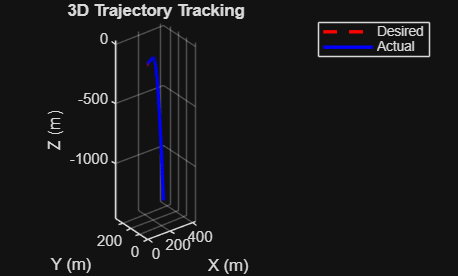

%% ============================================================
% MODULE 10 : Results Visualization
% ============================================================
% Plot all simulation results
% ============================================================
%% Figure 1 : 3D Trajectory
figure;
plot3(xd, yd, zd, 'r--', 'LineWidth', 2);
hold on;
plot3(position(1,:), position(2,:), position(3,:),'b', 'LineWidth', 2);
grid on;
axis equal;
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('3D Trajectory Tracking');
legend('Desired','Actual');

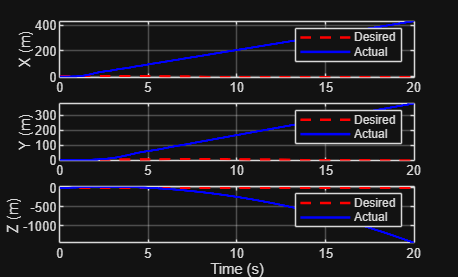

%% ============================================================
%% Figure 2 : Position Tracking
%% ============================================================
figure;
subplot(3,1,1)
plot(t, xd,'r--','LineWidth',1.5);
hold on;
plot(t, position(1,:),'b','LineWidth',1.5);
grid on;
ylabel('X (m)');
legend('Desired','Actual');
subplot(3,1,2)
plot(t, yd,'r--','LineWidth',1.5);
hold on;
plot(t, position(2,:),'b','LineWidth',1.5);
grid on;
ylabel('Y (m)');
legend('Desired','Actual');
subplot(3,1,3)
plot(t, zd,'r--','LineWidth',1.5);
hold on;
plot(t, position(3,:),'b','LineWidth',1.5);
grid on;
ylabel('Z (m)');
xlabel('Time (s)');
legend('Desired','Actual');

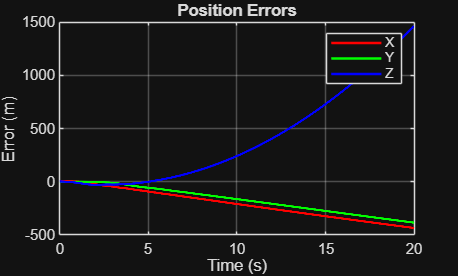

%% ============================================================
%% Figure 3 : Position Errors
%% ============================================================
figure;
plot(t, position_error(1,:), 'r','LineWidth',1.5);
hold on;
plot(t, position_error(2,:), 'g','LineWidth',1.5);
plot(t, position_error(3,:), 'b','LineWidth',1.5);
grid on;
xlabel('Time (s)');
ylabel('Error (m)');
title('Position Errors');
legend('X','Y','Z');

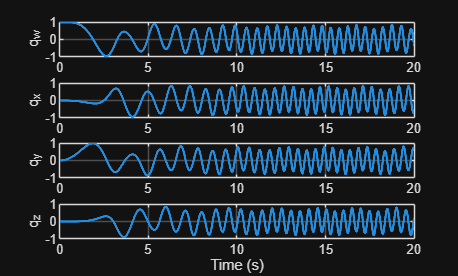

%% ============================================================
%% Figure 4 : Quaternion Components
%% ============================================================
figure;
subplot(4,1,1)
plot(t, quaternion(1,:),'LineWidth',1.5);
grid on;
ylabel('q_w');
subplot(4,1,2)
plot(t, quaternion(2,:),'LineWidth',1.5);
grid on;
ylabel('q_x');
subplot(4,1,3)
plot(t, quaternion(3,:),'LineWidth',1.5);
grid on;
ylabel('q_y');
subplot(4,1,4)
plot(t, quaternion(4,:),'LineWidth',1.5);
grid on;
ylabel('q_z');
xlabel('Time (s)');

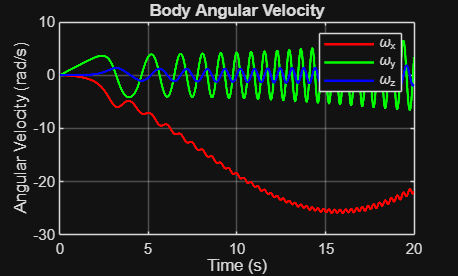

%% ============================================================
%% Figure 5 : Angular Velocity
%% ============================================================
figure;
plot(t, omega(1,:), 'r','LineWidth',1.5);
hold on;
plot(t, omega(2,:), 'g','LineWidth',1.5);
plot(t, omega(3,:), 'b','LineWidth',1.5);
grid on;
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
title('Body Angular Velocity');
legend('\omega_x','\omega_y','\omega_z');

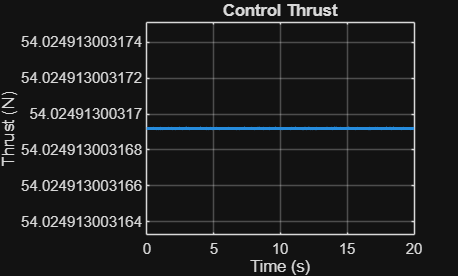

%% ============================================================
%% Figure 6 : Thrust
%% ============================================================
figure;
plot(t, thrust_cmd,'LineWidth',2);
grid on;
xlabel('Time (s)');
ylabel('Thrust (N)');
title('Control Thrust');

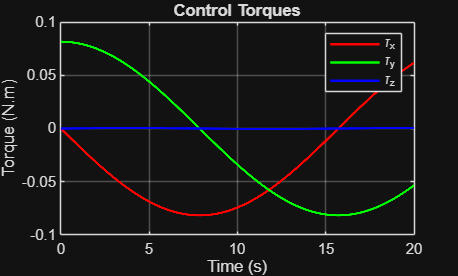

%% ============================================================
%% Figure 7 : Control Torques
%% ============================================================
figure;
plot(t, control_torque(1,:), 'r','LineWidth',1.5);
hold on;
plot(t, control_torque(2,:), 'g','LineWidth',1.5);
plot(t, control_torque(3,:), 'b','LineWidth',1.5);
grid on;
xlabel('Time (s)');
ylabel('Torque (N.m)');
title('Control Torques');
legend('\tau_x','\tau_y','\tau_z');

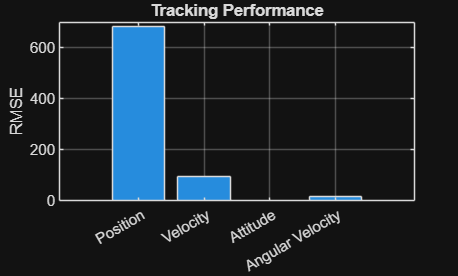

%% ============================================================
%% Figure 8 : RMSE Summary
%% ============================================================
figure;
RMSE = [RMSE_position ...
        RMSE_velocity ...
        RMSE_attitude ...
        RMSE_angular_velocity];
bar(RMSE);
grid on;
set(gca,'XTickLabel',{'Position','Velocity','Attitude','Angular Velocity'});
ylabel('RMSE');
title('Tracking Performance');